# Tutorial 2: Group-analysis of resting-state data

This example will perform multi-participant source-space MEG microstate analysis using the +microstate toolbox. This section will reproduce the analysis described in section 3.2 of the toolbox manuscript [1].

References:

[1] Tait and Zhang (2021) bioRxiv 2021.07.13.452193; doi: [https://doi.org/10.1101/2021.07.13.452193](https://doi.org/10.1101/2021.07.13.452193) 

[2] Tait and Zhang (2021) bioRxiv 2021.03.25.436979; doi: [https://doi.org/10.1101/2021.03.25.436979](https://doi.org/10.1101/2021.03.25.436979) 

If you have any errors or issues with this tutorial, please open an issue via the github issue tracker: [https://github.com/plus-microstate/toolbox/issues](https://github.com/plus-microstate/toolbox/issues) 

To use this Matlab live script, read through each section and try to understand what the code will do. Then press the "Run section" button (in the 'Live Editor' tab at the top of the Matlab control panel) to run each section and see the results inline. 

### Download the data and add to the path

The first thing we need to do is make sure the data is downloaded and that MATLAB can "see" the data. We have included a script to do this. The line of code below runs this script. If this is your first time running the tutorial, you will get a pop-up asking whether you wish to download the tutorial data. You must download this to proceed. 

**This data-set is reasonably large (3.38 GB) and can take a while to download. Please be patient. **

check_for_data

If you got an error in this section, you might not have the folder toolbox-master on your Matlab path. Make sure to add this folder to your path, and re-run this section.

### Read in 5000 GFP peaks per participant from the first resting-state scan

The data used in this tutorial was acquired, preprocessed, and source reconstructed as described in Tait and Zhang (2021) [2]. Here, we will perform a group-level microstate analysis of this data as described in [2]. The pipeline involves fitting microstates based on a small sample of 5000 GFP peaks per participant, and validating the microstate maps on the full datasets. For added validation of the generalizability of the microstates, each participant underwent two scans within one month of each other. Here, the 5000 GFP peaks are selected only from the 1st scan, while the 2nd scan will be used entirely as a test data set. While the simplest way to code this up would be to read in all the data at once, this is extremely memory intensive for large data sets. This tutorial only ever has a single data set read in at a given time. The first step is therefore to read in each data set one-by-one, and save only 5000 GFP peaks from that dataset in a microstate *cohort *object (described in more detail later). 

Firstly, we need to find files corresponding to scan-1 from each participant. The 2nd scan for each participant is used as validation only, so we do not want to use this data in the clustering. 

% Get a list of all files in the MEG-rest data directory which end in
% -rest-1.edf
scan1files = dir([datadir '/*-rest-1.edf']) ; 

Next, we need to initialize an empty microstate *cohort *object. While *individual* objects (introduced in tutorial 1) are used to store a single data set, *cohort* objects are used to store multiple datasets.

% Initialize an empty microstate cohort object
coh = microstate.cohort ; 

The next step involves looping over each of our resting-state (scan 1) files, reading that file's data into a microstate *individual *object (using the **import_edf **function), and then adding that *individual* to the cohort (using the third input to the **add_individuals** function to specify that we will save 5000 GFP peaks). 

% Loop over scans
for i = 1:length(scan1files)
    
    % Make an empty microstate individual
    ms = microstate.individual; 

    % Read in the data
    filename = [scan1files(i).folder '/' scan1files(i).name] ; 
    modality = 'source' ; % could be 'eeg' or 'meg' instead
    ms = ms.import_edf(filename,modality) ;

    % Load in the artifacts
    filename = [scan1files(i).folder '/Artifacts/artfct-' scan1files(i).name(1:end-3) 'json'] ; 
    bad_samples = artifacts_json2badsamples(filename) ; 

    % Add the artifacts
    ms = ms.add_bad_samples(bad_samples) ; 
    
    % Add the individual to the cohort
    coh = coh.add_individuals(ms,'scan1',5000) ; 

end

If you got an error on the previous lines of code, you may not have installed the tutorial data. Try entering `microstate.functions.install('data')` in the command window, and this should download the tutorial data. 

Let is take a look at the *cohort* object and see what it looks like.

coh

coh =   cohort with properties:

         individual: [30×1 microstate.individual]
          condition: [30×1 double]
    conditionlabels: {'scan1'}
         globalmaps: []
              stats: [1×1 struct]
            process: [30×2 table]


The property `coh.individual` contains each of our 30 microstate individuals. Here, `coh.condition` is a vector with all entries equal to 1, and `coh.conditionlabels` is a cell of length 1 containing a string reading 'scan1'. Later, when we read in both scan-1 and scan-2, you'll see that `coh.conditionlabels={'scan1','scan2'}`, and `coh.condition(i)` is 1 if that individual was from scan-1 and 2 if that individual was from scan-2. Hence, conditions are useful for differentiating between different datasets. Tutorial 3 will introduce conditions further by simulating some data recorded under two experimental conditions. 

### **Perform microstate analysis**

Next, we will run the microstate analysis. Typically preprocessing would be performed prior to microstate analysis, but the data here is already preprocessed appropriately. 

We can use the function **cluster_globalkoptimum** to perform group-level microstate analysis. This function will identify the optimum number of microstates and perform the clustering. The code below which is commented out shows how to perform this analysis (note we search for k between 2 and 40 states following [2]), but this is extremely time consuming and takes many hours. You are free to uncomment this code and run it, but if so we recommend doing this overnight. 

% coh = coh.cluster_globalkoptimum('kmin',2,'kmax',40); 
% 
% or, for more info: 
% 
% [coh,optimum_k,k_values,maps_all_k,gev_all_k] = coh.cluster_globalkoptimum('kmin',2,'kmax',40); 

Instead, included in the toolbox is the result of one run of this code that we ran in advance (in fact, this is the run presented in [2]). For demonstration purposes in this tutorial, we will instead load in this run. ***It is important to note here that since the k-means algorithm has random initial conditions, and since we randomly sampled 5000 GFP peaks per participant, multiple runs of the code give slightly different outputs each time. A full analysis of the variability over 250 runs (restricting to 10 states and 1 k-means replicate, vs the original run which varied 2-40 states and 20 replicates for each version) is presented in [2], and for transparency here we have additionally included the output maps for each of the 250 runs in the variable `repetition_maps`. An extra exercise is to try plotting some of these additional repetitions, to visualise the degree to which the microstate estimation varies across runs.*** 

In the code below, we load in the run: 

load('cluster_globalkoptimum_output.mat')

### Analyse and visualise the microstate data

To plot the resulting maps, we first need a 3d brain atlas. To do so, we use the **functions.layout_creator** function in the same way as we did in the first tutorial to make a 2d electrode layout. The layout_creator contains a number of brain atlases including AAL, AFNI, Brainnetome, and HCP230. The latter was used in this study. In the data directory (MEG-rest), there is a file called ROIlabels.txt. We can read this in to specify the order of the ROIs in our data. 

% Call layout creator
template = 'hcp230' ; % Use the HCP230 atlas template
labels = readcell([datadir '/ROIlabels.txt'],'Delimiter','\n'); % equivalent to data.label
layout = microstate.functions.layout_creator(template,labels) ; 

As in the previous tutorial, we can also call the GUI to create the layout, but we will not do this here. 

Now we can plot the data. Much like the *individual *object, the *cohort *object has a method associated with it called **plot **for all visualisation, so we can simply call this function specifying we wish to plot the maps. In line with [2], we additionally specify the input `'cscale',[0.5,1]`, which essentially thresholds at 50% of maximum activation in the map (specifically setting the colour axis between 50% and 100% maximum activation for each map). 

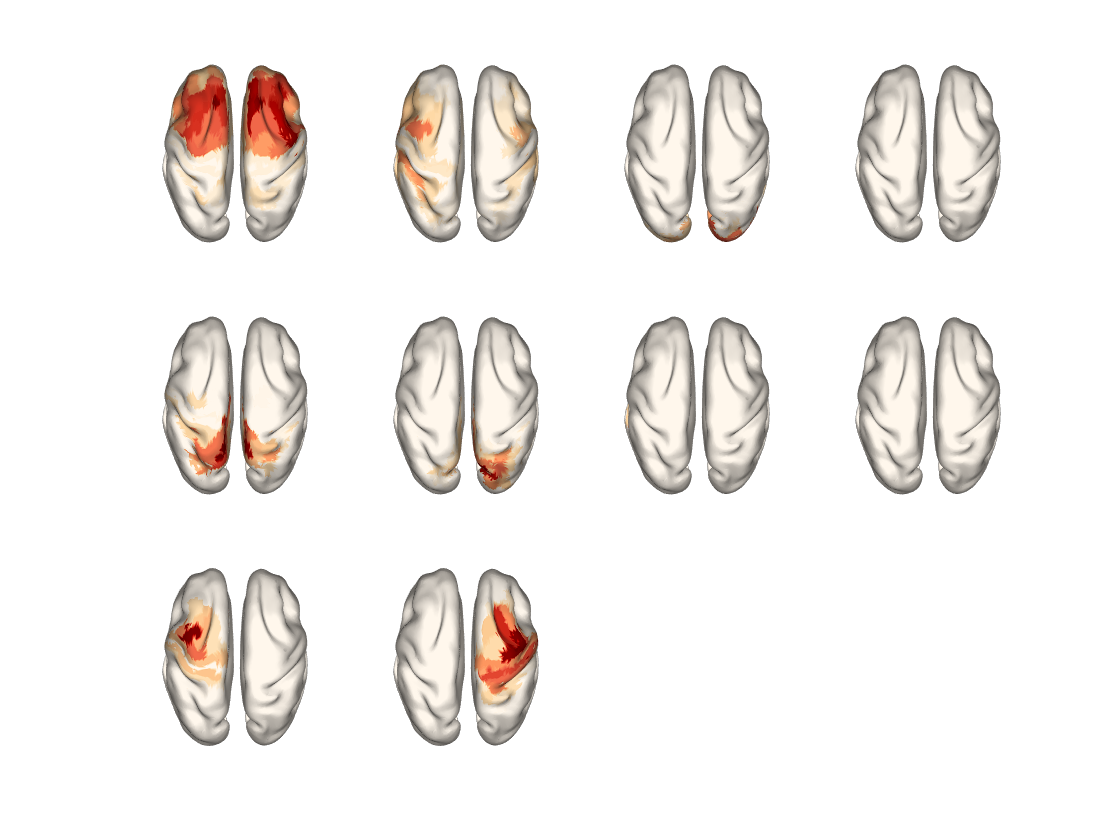

coh.plot('globalmaps',layout,'cscale',[0.5,1]) ; 

By clicking the "Open in figure window" button in the top right of the figure, you can interactively rotate these plots to view the full surface. 

### Back-fit to the data and calculate GEV

We now have some microstate maps, so the next step is to back-fit these maps to the data in order to obtain microstate sequences for each scan. We will subsequently calculate global explained variance (GEV), to test how well the microstates estimated from 5000 GFP peaks fit the whole data set (scan 1) and a new data set (scan 2, not used for clustering). 

Firstly, let us save the global maps from the clustering as a new variable, and then clear our *cohort* object, which is no longer required. 

globalmaps = coh.globalmaps ; clear coh

Next, we will loop over each dataset. We will read in the data to a microstate *individual*, assign the global maps to the *individual*, back-fit the global maps to the data, and calculate GEV. Finally, since we no longer need the data (we are only interested in the microstate sequences and statistics such as GEV), we will add the *individual* to a *cohort* object but set the third input to **add_individuals** to 0, meaning data is not saved in the cohort. By doing the analysis this way, we do not need to worry about having many MEG datasets being read into memory at a given time. 

% Get a list of all MEG files in the MEG-rest data directory
allMEGfiles = dir([datadir '/*-rest-*.edf']) ; 

% Initialize an empty microstate cohort object
coh = microstate.cohort ; 

% Loop over scans
rng('default') % for reproducibility
for i = 1:length(allMEGfiles)
    
    % Make an empty microstate individual
    ms = microstate.individual; 

    % Read in the data
    filename = [allMEGfiles(i).folder '/' allMEGfiles(i).name] ; 
    modality = 'source' ; % could be 'eeg' or 'meg' instead
    ms = ms.import_edf(filename,modality) ;

    % Load in the artifacts
    filename = [allMEGfiles(i).folder '/Artifacts/artfct-' allMEGfiles(i).name(1:end-3) 'json'] ; 
    bad_samples = artifacts_json2badsamples(filename) ; 

    % Add the artifacts
    ms = ms.add_bad_samples(bad_samples) ; 

    % Add the global maps to the microstate individual
    ms.maps = globalmaps ; 

    % Backfit the globalmaps to the data
    ms = ms.cluster_alignmaps ; 

    % Calculate GEV
    ms = ms.stats_gev ; 
    
    % Add the individual to the cohort but don't save the data
    scanNum = allMEGfiles(i).name(end-4) ; % 1 if first scan, 2 if 2nd scan
    condition = ['scan' scanNum] ; % scan1 if first scan, scan2 if 2nd
    coh = coh.add_individuals(ms,condition,0) ; 

end

### Plot GEV in 1st and 2nd scans

Now, we can plot the GEV in the 1st and 2nd resting-state scans using the **plot** function. The first step to doing this is to collate all the GEV values into a vector for each condition, which uses the **cohort_stats** function. Before using the **cohort_stats** function, the stats are saved for each individual separately, e.g. see the outputs of the code below

coh.stats

ans = struct with no fields.


coh.individual(1).stats.gev

ans = 0.6167

Note how coh.`stats` is empty, and to see the GEV for any individual we have to look at their *individual* object. This makes direct comparisons tricky, as the data needs collating into a useable format. This is the function of **cohort_stats**.

coh = coh.cohort_stats ; 
coh.stats

ans = 1×2 struct array with fields:
    gev


Now see how `coh.stats` contains a field called `gev`. Let us inspect that field:

[coh.stats.gev]

ans =     0.6167    0.6151
    0.6500    0.6571
    0.6383    0.6424
    0.7689    0.6254
    0.6468    0.5954
    0.6994    0.6231
    0.6500    0.6443
    0.6122    0.6328
    0.6378    0.6314
    0.6351    0.6492


Each condition (i.e. 1st scan and 2nd scan) now has the GEV from all scans within that condition neatly organised in a vector. We can view, for example, the mean GEV in each condition using the following code: 

mean([coh.stats.gev])

ans =     0.6429    0.6251


Similarly we can calculate other statistics such as median, standard error, etc. To plot the GEV values, we can use the following: 

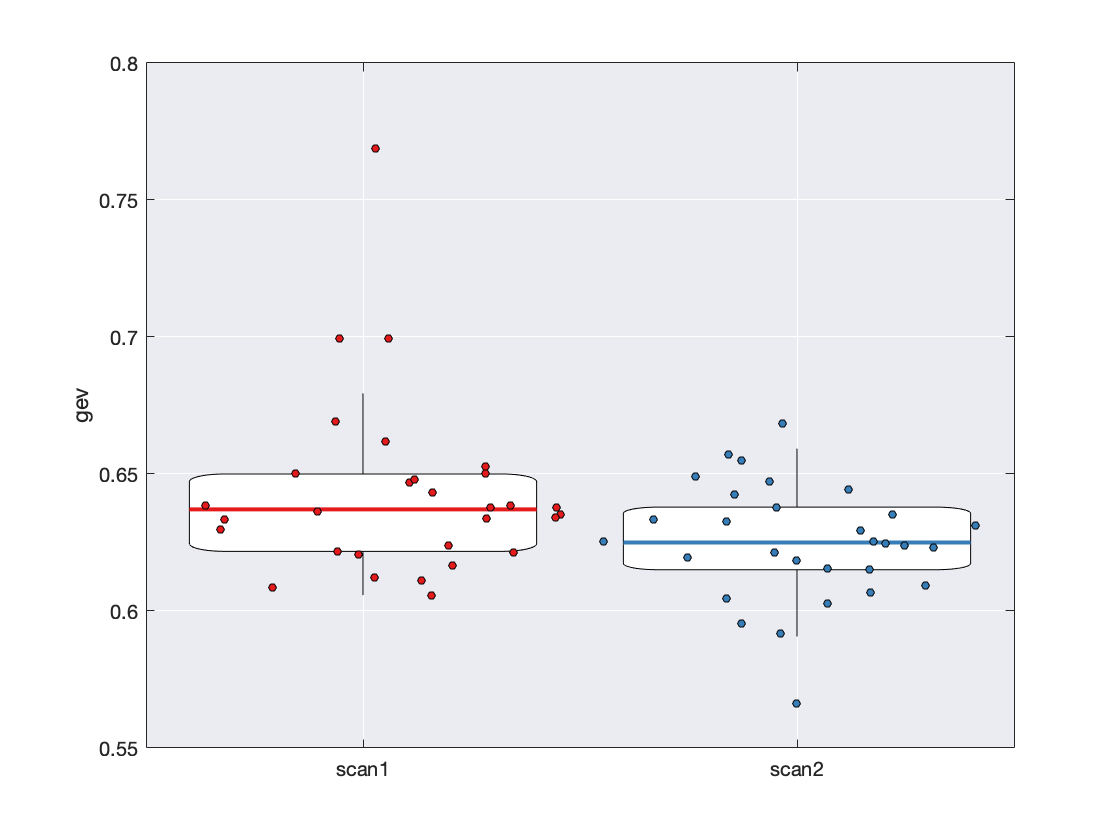

figure
coh.plot('gev');

### Microstate segmented functional connectivity

Using +microstate, we can also examine microstate segmented functional connectivity. In this section, we will replicate the analysis of [2] (with some minor changes for speed/efficiency for the purposes of this tutorial) to demonstrate a significant relationship between functional connectivity and microstate class. 

To calculate microstate segmented functional connectivity for each state, we can replace line 78 of the code above (which calculated GEV using the code `ms = ms.stats_gev`) with the code: 

`nets(i,:) = ms.networks_wpli([8,13]) ;`

The input `[8,13]` specifies that we want to calculate alpha band networks (8-13 Hz). Similarly we could look at any other frequency band, such as theta (4-8 Hz) or beta (13-30 Hz). 

This code is very time consuming, taking several hours on a typical standard desktop computer. We have therefore run this code for you, and the code below reads in the output. 

load('microstate_segmented_wpli.mat','nets')

Note the output is a 60x10 cell, corresponding to 60 scans (2 scans each for 30 participants) and 10 microstate classes. Each element is a 230x230 matrix containing a network. 

The following line of code calls a custom function saved in the tutorial2_RestingSource_Group folder. This function does not specifically use +microstate functions, so for brevity and simplicity of this tutorial we have not detailed the MATLAB codes. However, the codes can be viewed by typing `open mvpa_analysis` in the console. This function reproduces the analysis of [2], using multivariate pattern analysis (MVPA) to test the relationship between degree distribution and microstate class. While [2] used a specialised MVPA toolbox allowing for more sophisticated machine learning and analysis, here we use simple MATLAB functions from the statistics and machine learning toolbox. A 10-class LDA classifier is built to predict microstate class from the degree distribution, and 10-fold cross-validated. Classification accuracy is compared against 200 'null' datasets (reduced from 2000 in [2] for computaitonal speed) in which the microstate labels are permuted, destroying any potential relationships between degree distribution and microstate label. 

rng('default') ; % for reproducibility
pval = mvpa_analysis(nets)  

pval = 0.0050

We obtained a p-value of 1/200 (the minimum possible p-value with 200 permutations), suggesting a strong relationship between microstate class and functional connectivity pattern. 

We can use +microstate to plot the microstate-segmented functional connectivity. The function below calculates the average network in each microstate class, `nets_avg.`

nets_avg = average_nets(nets) ; 

Let us now plot the average network in each class using +microstate's **networks_plot** function. 

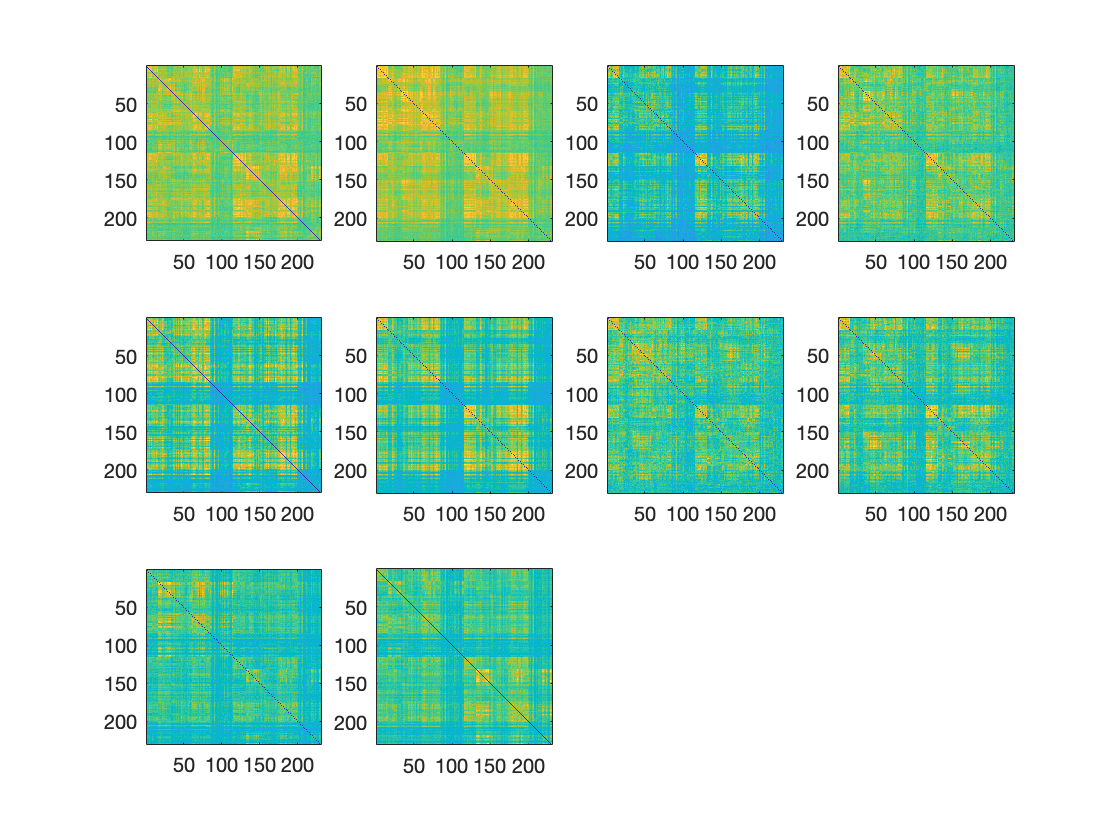

microstate.functions.networks_plot(nets_avg) ; 

We can additionally specify a layout to plot the network as a graph, thresholding at the top 2.5% of edges: 

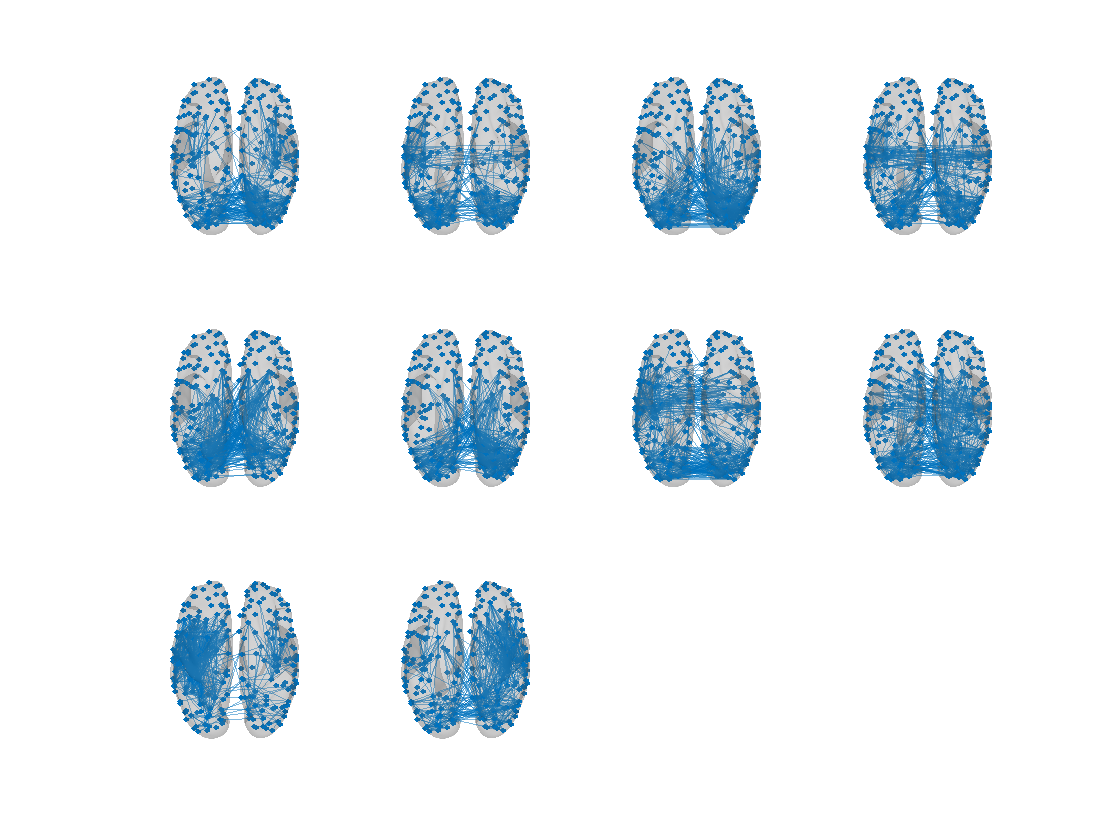

figure
microstate.functions.networks_plot(nets_avg,layout,'density',0.025) ; 

Note that these networks appear different to those in [2]. This is because here we have not normalized against a baseline, whereas in [2] the plots were normalized against the static connectivity. In this data, static connectivity is largely driven over the visual cortex, and hence microstate-segmented connectivity patterns also primarily show connectivity over the cortex. An exercise left to the user is to try and recreate the networks in [2] by plotting your networks baselined against static connectivity. Static connectivity can be calculated in **networks_wpli** by specifying the 5th input to be `true`. You can normalize networks against a baseline network when using the **networks_plot** function by specifying a name-value pair argument `'baseline',baseline_network.` 

** There is an important distinction to note between the MVPA analysis performed here and that of [2]. In the analysis performed here, we use a single network per microstate per scan, resulting in a total of 600 networks used for classification. In [2], data was segmented into 5 second epochs and networks were derived for each epoch, resulting in >5000 networks. To do the analysis this way, you can specify a 2nd input `true` to **networks_wpli**, which flags the data  to keep the network for each epoch. 